# ME 419 Lab 1

**Names:** Julia Fay, Aiden Taylor 

**Date:** 2024.1.11

**Class:** ME419

**Description: **The purpose of this file is to simulate various first and second order mechanical systems using simulink.

## Exercise 1

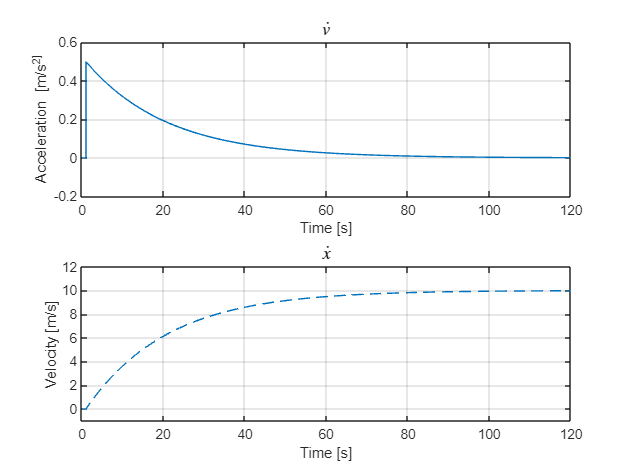

subplot (2,1,1);            %start the subplot
x = sim('Lab1_419_simul');  %run simulink simulation
plot(x.tout, x.simout(:,1));%plot acceleration
grid on;
title('$\dot{v}$', 'Interpreter', 'latex','FontSize',12,'FontWeight','bold')  
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')
axis([0 120 -0.2 0.6])
subplot(2,1,2);             %plot velocity
plot(x.tout, x.simout(:,2), '--')
grid on;
title("$\dot{x}$", 'Interpreter', 'latex','FontSize',12,'FontWeight','bold');
xlabel('Time [s]')
ylabel('Velocity [m/s]')
axis([0 120 -1 12])

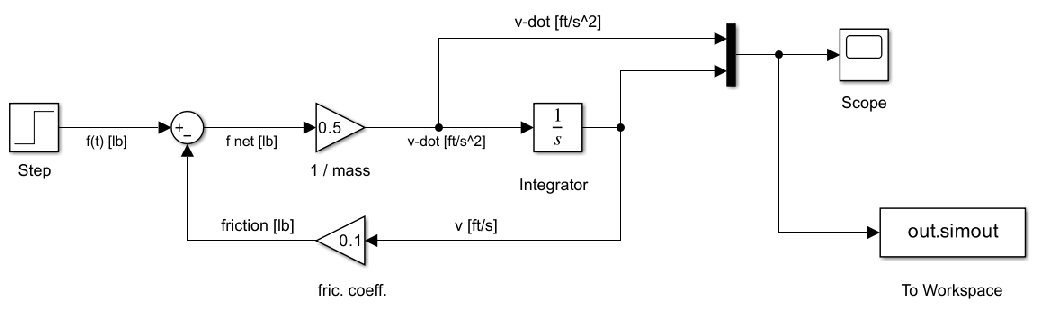

snapshotModel('Lab1_419_simul') %output simulink image

## Exercise 2

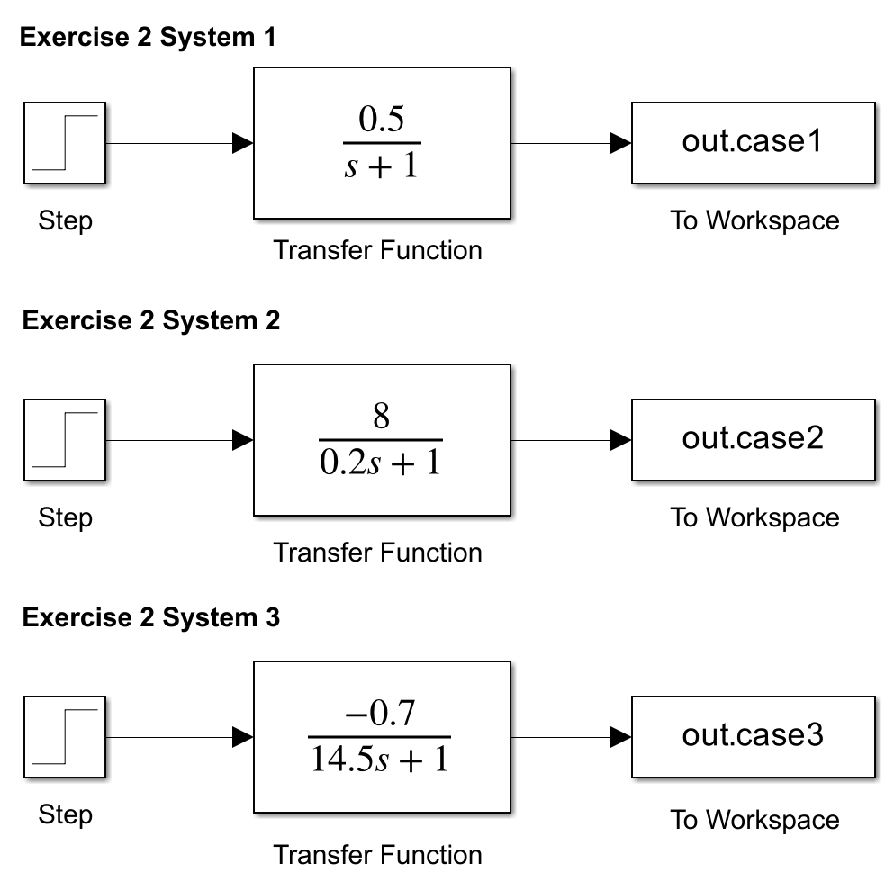

%run the block diagram 
run = sim("Lab1_Exercise2_BD.slx");

%import the block diagram image 
snapshotModel('Lab1_Exercise2_BD') 

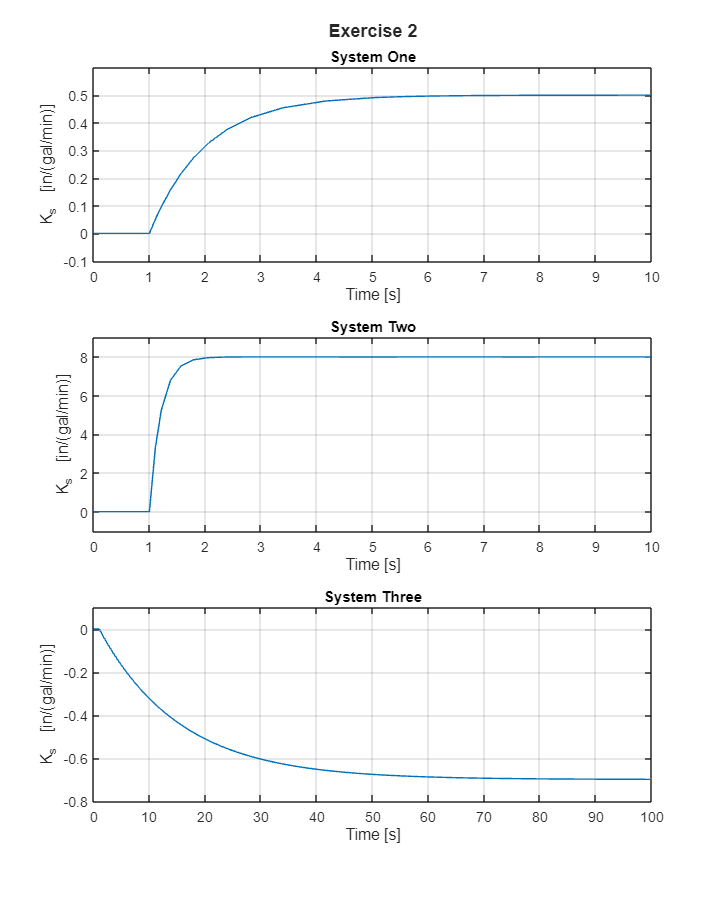


%create a tiled layout 
fig1 = figure();
tl = tiledlayout(3,1);         
title(tl,'Exercise 2','FontSize',12,'FontWeight','bold');
fig1.Position(3:4) = [560*3 420*5]; %scale subplot

%plot the results for case 1 and format
nexttile; 
plot(run.tout,run.case1)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 10 -0.1 0.6]);
title('System One','FontSize',10,'FontWeight','bold');
grid on

%case 2
%plot the results for case 2 and format
nexttile; 
plot(run.tout,run.case2)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 10 -1 9]);
title('System Two','FontSize',10,'FontWeight','bold');
grid on

%case 3
%plot the results for case 3 and format
nexttile;
plot(run.tout,run.case3)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 100 -0.8 0.1]);
title('System Three','FontSize',10,'FontWeight','bold');
grid on

## Exercise 3

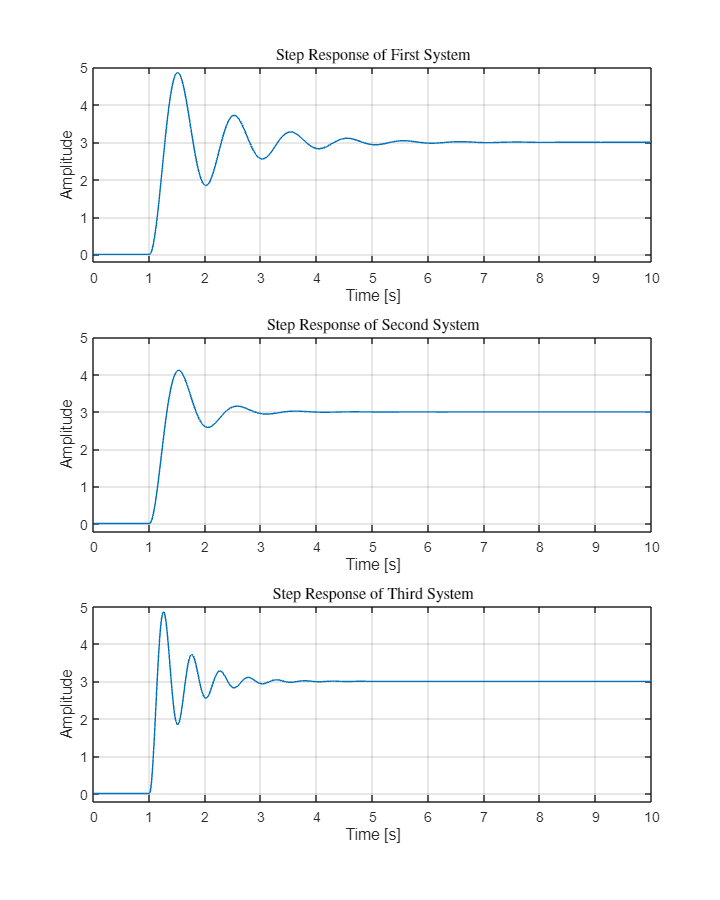

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
y = sim('Lab1_419_simul3');         %run simulink
subplot (3,1,1);                    %plot sys 1
plot(y.tout, y.simout(:,1));
grid on;
title('Step Response of First System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,2);                     %plot sys 2
plot(y.tout, y.simout1(:,1));
grid on;
title('Step Response of Second System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,3);                     %plot sys 3
plot(y.tout, y.simout2(:,1));
grid on;
title('Step Response of Third System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

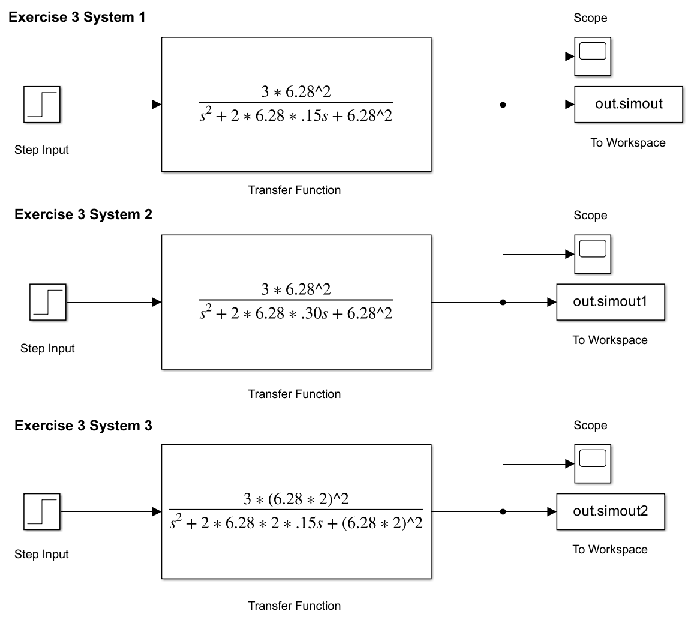

snapshotModel('Lab1_419_simul3')

## Exercise 4

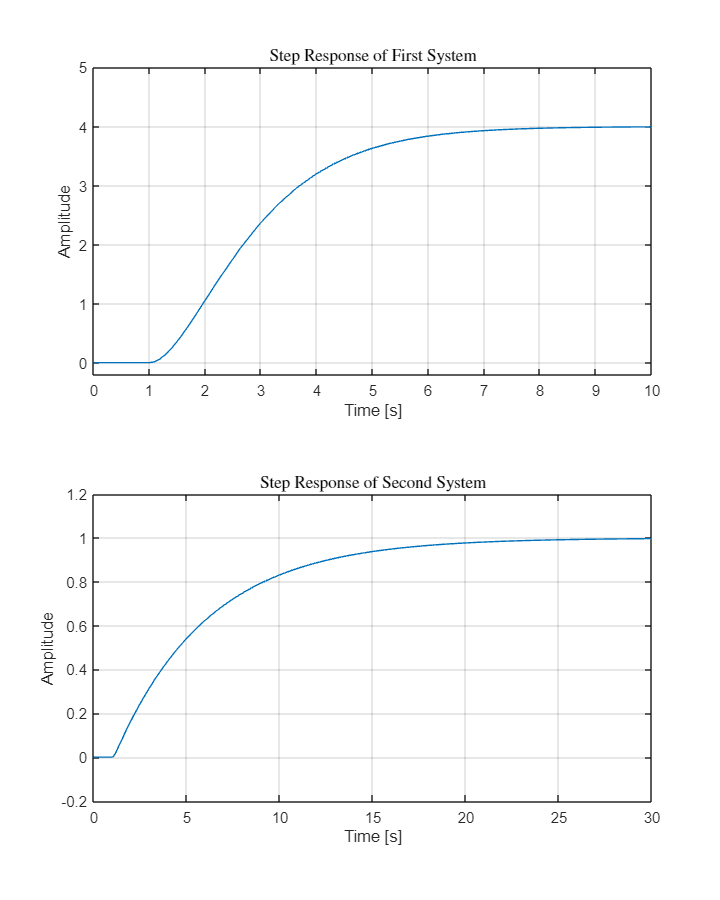

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
z = sim('Lab1_419_simul4');         %run simulink
subplot (2,1,1);                    %plot sys 1
plot(z.tout, z.simout(:,1));
grid on;
title('Step Response of First System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])
subplot (2,1,2);                    %plot sys 1
plot(z.tout, z.simout1(:,1));
grid on;
title('Step Response of Second System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 30 -0.2 1.2])

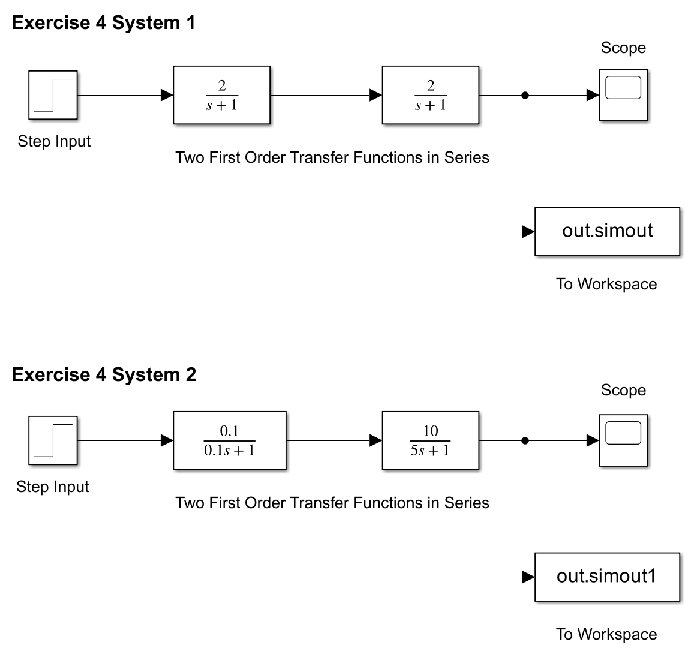

snapshotModel('Lab1_419_simul4')

## Exercise 5

%run the block diagram 
run5 = sim("Lab1_419_sim5.slx");

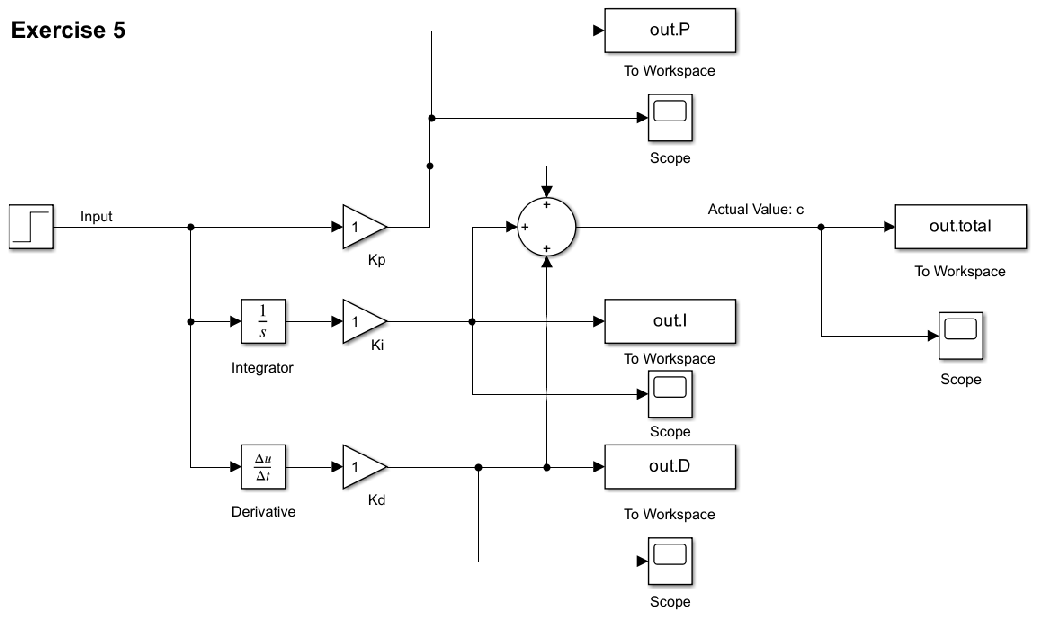


%import the block diagram image 
snapshotModel('Lab1_419_sim5') 

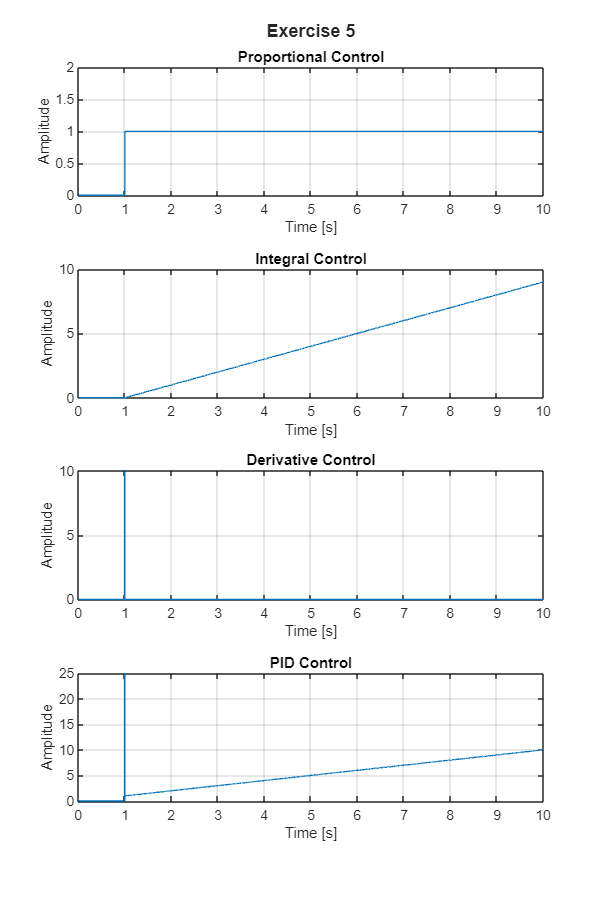


%create a tiled layout 
fig5 = figure();
t5 = tiledlayout(4,1);         
title(t5,'Exercise 5','FontSize',12,'FontWeight','bold');
fig5.Position(3:4) = [560*3 420*6]; %scale subplot

%plot the results for Proportional Control and format
nexttile; 
plot(run5.tout,run5.P)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 2]);
title('Proportional Control','FontSize',10,'FontWeight','bold');
grid on

%plot the results for Integral Control and format
nexttile; 
plot(run5.tout,run5.I)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 10]);
title('Integral Control','FontSize',10,'FontWeight','bold');
grid on

%plot the results for Derivative Control and format
nexttile; 
plot(run5.tout,run5.D)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 10]);
title('Derivative Control','FontSize',10,'FontWeight','bold');
grid on

%plot the results for Total Control and format
nexttile; 
plot(run5.tout,run5.total)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 25]);
title('PID Control','FontSize',10,'FontWeight','bold');
grid on

## Exercise 6

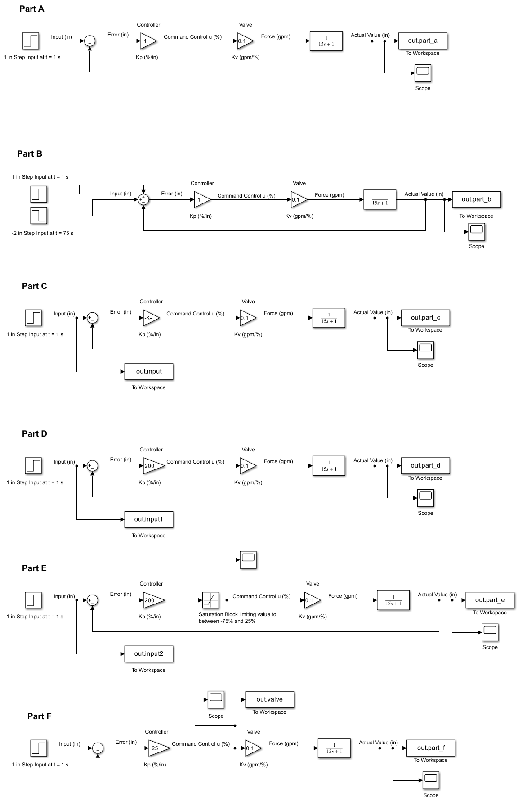

%run the block diagram 
run6 = sim("Lab1_419_sim6.slx");

%import the block diagram image 
snapshotModel('Lab1_419_sim6') 

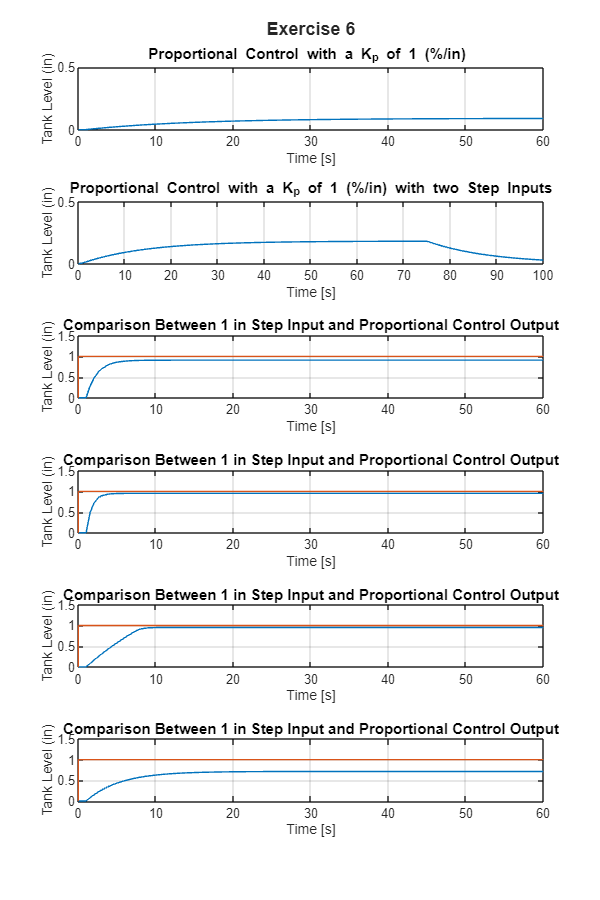


%create a tiled layout 
fig6 = figure();
t6 = tiledlayout(6,1);         
title(t6,'Exercise 6','FontSize',12,'FontWeight','bold');
fig6.Position(3:4) = [560*5 420*10]; %scale subplot

%PART A
nexttile; 
plot(run6.tout,run6.part_a)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 0.5]);
title('Proportional Control with a K_p of 1 (%/in) ','FontSize',10,'FontWeight','bold');
grid on

%PART B
nexttile; 
plot(run6.tout,run6.part_b)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 100 0 0.5]);
title('Proportional Control with a K_p of 1 (%/in) with two Step Inputs','FontSize',10,'FontWeight','bold');
grid on

%PART C
nexttile; 
plot(run6.tout,run6.part_c)
hold on 
fix = [run6.input;1;1;1;1;1;1;1;1;1;1];
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on
%add legend, show percent error and time constant on the plot 


%PART D 
nexttile; 
plot(run6.tout,run6.part_d)
hold on 
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on
%add legend, show percent error and time constant on the plot 


%PART E 
nexttile; 
plot(run6.tout,run6.part_e)
hold on 
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on
%PART F 
nexttile; 
plot(run6.tout,run6.part_f)
hold on 
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on

## Exercise 7

%run the block diagram 
run7 = sim("Lab1_419_sim7.slx");

%import the block diagram image 
snapshotModel('Lab1_419_sim7') 


desired = 18 %get the absolute desired tank level from the user

desired = 18

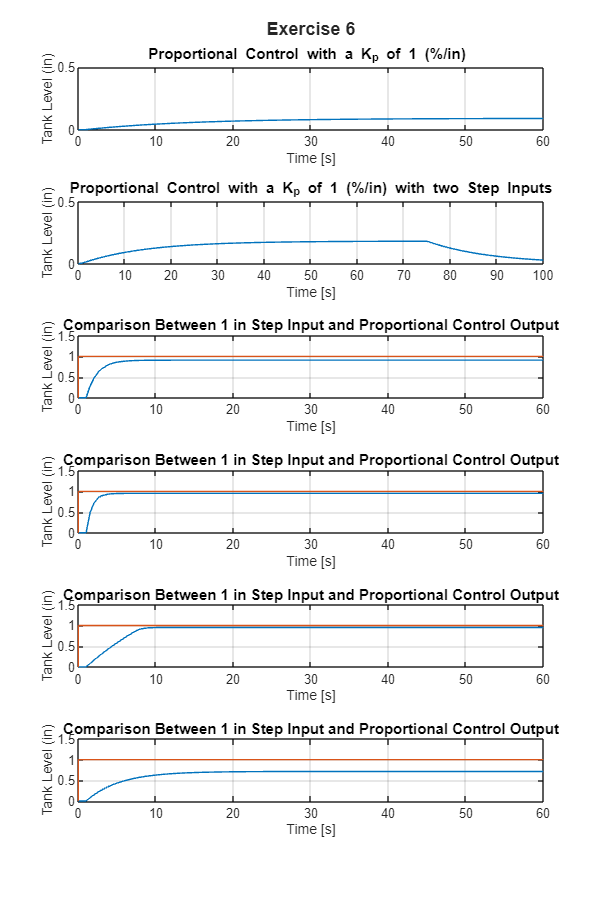


%create a tiled layout 
fig7 = figure();
t7 = tiledlayout(6,1);         
title(t7,'Exercise 6','FontSize',12,'FontWeight','bold');
fig7.Position(3:4) = [560*5 420*10]; %scale subplot

%PART A
nexttile; 
plot(run7.tout,run7.part_a)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 0.5]);
title('Proportional Control with a K_p of 1 (%/in) ','FontSize',10,'FontWeight','bold');
grid on

%PART B
nexttile; 
plot(run7.tout,run7.part_b)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 100 0 0.5]);
title('Proportional Control with a K_p of 1 (%/in) with two Step Inputs','FontSize',10,'FontWeight','bold');
grid on

%PART C
nexttile; 
plot(run7.tout,run7.part_c)
hold on 
fix = [run7.input;1;1;1;1;1;1;1;1;1;1];
plot(run7.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on
%add legend, show percent error and time constant on the plot 


%PART D 
nexttile; 
plot(run7.tout,run7.part_d)
hold on 
plot(run7.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on
%add legend, show percent error and time constant on the plot 


%PART E 
nexttile; 
plot(run7.tout,run7.part_e)
hold on 
plot(run7.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on
%PART F 
nexttile; 
plot(run7.tout,run7.part_f)
hold on 
plot(run7.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
title('Comparison Between 1 in Step Input and Proportional Control Output','FontSize',10,'FontWeight','bold');
grid on

## Exercise 8

run8 = sim('Lab1_419_sim8');
fig8 = figure();
plot(run8.tout, run8.p1)
xlim([1 1.25])
hold on
yline(run8.p1(1421))
yline(max(run8.p1), color='red')
idx = find(run8.p1 == max(run8.p1));
xline(run8.tout(idx), color='magenta')
idxs = find(run8.p1(150:1400) == max(run8.p1(150:1400))) + 150;
dampedper = run8.tout(idxs)-run8.tout(idx)

dampedper = 0.0203

percover = 100 * (max(run8.p1) - run8.p1(1421)) / run8.p1(1421)

percover = 77.0738

clgain = run8.p1(1421)

clgain = 0.6970

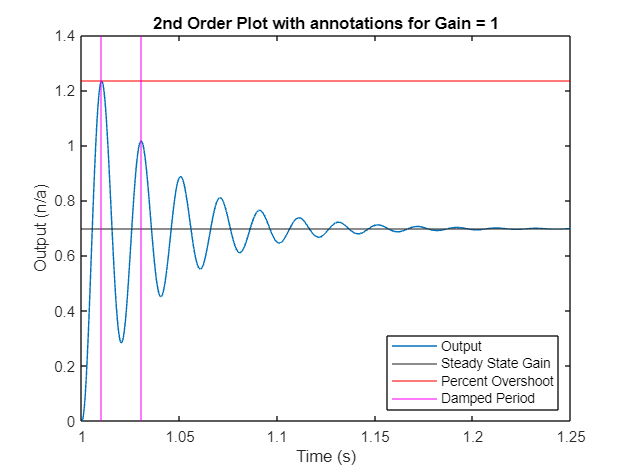

xline(run8.tout(idxs), color='magenta')
legend('Output', 'Steady State Gain', 'Percent Overshoot', 'Damped Period', 'Location', 'southeast')
title('2nd Order Plot with annotations for Gain = 1')
xlabel('Time (s)')
ylabel('Output (n/a)')
hold off

We observe an underdamped system with the following parameters: 

Closed Loop Gain = .6947

Percent Overshoot = 77.07%

Damped Oscillation Period = 0.0203 seconds

Our values from block diagram algebra are: 

When doubling the gain, we predict that the overshoot will increase and also the steady state gain will slightly increase. Additionally we expect the damped period to decrease. We find this to be true when running the simulation, and is highlighted by the plot annotations below.

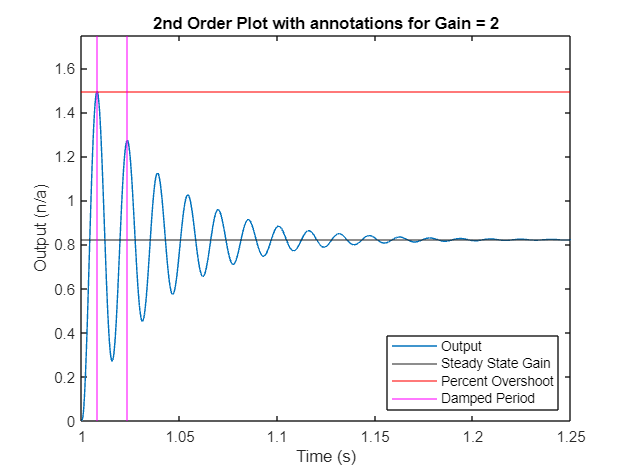

fig9 = figure();
plot(run8.tout, run8.p2)
yline(run8.p2(1421))
yline(max(run8.p2), color='red')
idx = find(run8.p2 == max(run8.p2));
xline(run8.tout(idx), color='magenta')
idxs = find(run8.p2(150:1400) == max(run8.p2(150:1400))) + 150;
xline(run8.tout(idxs), color='magenta')
legend('Output', 'Steady State Gain', 'Percent Overshoot', 'Damped Period', 'Location', 'southeast')
xlim([1 1.25])
ylim([0 1.75])
title('2nd Order Plot with annotations for Gain = 2')
xlabel('Time (s)')
ylabel('Output (n/a)')

dampedper = run8.tout(idxs)-run8.tout(idx)

dampedper = 0.0157

percover = 100 * (max(run8.p2) - run8.p2(1421)) / run8.p2(1421)

percover = 81.9109

clgain = run8.p2(1421)

clgain = 0.8214

The above calculations support our prediction.